# Proyecto Integrador III - Planificación dinámica con RRT*

Integrantes:  - William Andrade Gonzalez

                     - Glen Alejandro Guerrero Burbano

## GENERAR EL MAPA Y ENGROSAR OBSTACULOS

Se crea el mapa con los obstaculos

clear; clc; close all;
disp("Punto INICIAL de la trayectoria en un mapa de 20x20 metros^2")

Punto INICIAL de la trayectoria en un mapa de 20x20 metros^2


p_inicial = input("Ingrese la posición INICIAL del robot como vector en metros [X, Y]: ");

disp("Punto FINAL de la trayectoria")

Punto FINAL de la trayectoria


p_final = input("Ingrese la posición FINAL del robot como vector en metros [X, Y]: ");

%Se multiplican por 10 para pasar de metros a pixeles de la imagen inicial
q_start = [(p_inicial(1)*10), (p_inicial(2)*10)];
q_goal  = [(p_final(1)*10), (p_final(2)*10)]; 

%q_start = [5, 15];
%q_goal  = [45, 35]; 

% 1. Generar el mapa inicial
addpath("auxiliar");
map = dibujarMapaV2(q_start, q_goal,'mapa_optimizado.png');
[rows, cols] = size(map); 

## Parametros simulación obstaculos y trayectorias emergentes

max_obstaculos_dinamicos = 2; % Límite de obstáculos que aparecerán
obs_generados = 0;
trayectoria_count = 1;
colores_rutas = lines(10); % Genera una paleta de 10 colores distintos

## Llamado función del planificador RRT*

% 2. Planificación Inicial
fprintf('--- PLANIFICACIÓN INICIAL ---\n');

--- PLANIFICACIÓN INICIAL ---


[path, found] = rrtStar(map, q_start, q_goal);

Iniciando RRT* (10000 iteraciones)...

--- ÉXITO ---
Coste: 245.82 | Nodos: 5418 | Tiempo: 1.3335s



if ~found
    error('Fallo al encontrar la ruta inicial. Verifica las coordenadas.');
end

## Simulación movimiento robot y obstáculos aleatorios

Se ha generado una simulación donde se simula el movimiento del robot con la matriz PATH que representa las coordenadas x,y de los nodos que sigue la trayectoria del robot (Es una movimiento ideal); En la práctica este movimiento deberá ser implementado con los algoritmos de lectura de sensores o odometría e incluso al control del robot. Por ahora se lo hace de una manera ideal desde simulación para enfocarse más en la planificación.

% Dibujar ruta inicial y enumerarla
plot(path(:,1), path(:,2), 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
text(path(1,1) + 1, path(1,2) + 2, sprintf('Ruta %d', trayectoria_count), ...
    'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
h_robot = plot(path(1,1), path(1,2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% 3. Simulación de Movimiento y Replanificación
idx = 1;

% El obstáculo aparecerá aleatoriamente entre el paso 3 y 5 de la ruta actual
paso_aparicion_obs = randi([5, 10]); 

fprintf('\n--- INICIANDO MOVIMIENTO ---\n');


--- INICIANDO MOVIMIENTO ---


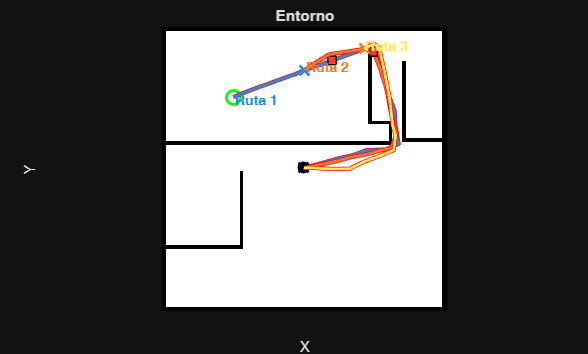


ALERTA: Obstáculo # 1 detectado.


Ruta 1 bloqueada. 
 Planificando nueva ruta...


Iniciando RRT* (10000 iteraciones)...

--- ÉXITO ---
Coste: 189.23 | Nodos: 6988 | Tiempo: 2.0772s


>>> Ruta 2 encontrada.



ALERTA: Obstáculo # 2 detectado.


Ruta 2 bloqueada. 
 Planificando nueva ruta...


Iniciando RRT* (10000 iteraciones)...

--- ÉXITO ---
Coste: 152.81 | Nodos: 6373 | Tiempo: 1.7440s


>>> Ruta 3 encontrada.


while idx <= size(path, 1)
    % Actualizar posición del robot
    current_pos = path(idx, :);
    set(h_robot, 'XData', current_pos(1), 'YData', current_pos(2));
    drawnow;
    pause(0.2); 
    
    % --- APARICIÓN ALEATORIA DE OBSTÁCULO CERCA DEL INICIO ---
    if idx == paso_aparicion_obs && obs_generados < max_obstaculos_dinamicos
        fprintf('\nALERTA: Obstáculo # %d detectado.\n', obs_generados + 1);
        
        % Colocar obstáculo un par de nodos adelante en su trayectoria actual
        obs_idx = min(idx + 2, size(path,1));
        obs_x = round(path(obs_idx, 1));
        obs_y = round(path(obs_idx, 2));
        
        % Límites del nuevo bloque de obstáculo
        r_min = max(1, obs_y-3); r_max = min(rows, obs_y+3);
        c_min = max(1, obs_x-3); c_max = min(cols, obs_x+3);
        
        % Insertar obstáculo en el mapa y dibujarlo
        map(r_min:r_max, c_min:c_max) = 1;
        patch([c_min c_max c_max c_min], [r_min r_min r_max r_max], ...
              [1 0.2 0.2], 'EdgeColor', 'k', 'FaceAlpha', 0.9);
        drawnow;
        
        obs_generados = obs_generados + 1;
        
        % --- DETECCIÓN DE INVALIDEZ ---
        ruta_invalida = false;
        for j = idx:(size(path,1)-1)
            if isCollision(path(j,:), path(j+1,:), map)
                ruta_invalida = true;
                break;
            end
        end
        
        if ruta_invalida
            fprintf('Ruta %d bloqueada. \n Planificando nueva ruta...\n', trayectoria_count);
            plot(current_pos(1), current_pos(2), 'x', 'Color', colores_rutas(trayectoria_count,:), 'MarkerSize', 10, 'LineWidth', 2); 
            
            % --- REPLANIFICAR ---
            [new_path, found_new] = rrtStar(map, current_pos, q_goal);
            
            if found_new
                trayectoria_count = trayectoria_count + 1;
                fprintf('>>> Ruta %d encontrada.\n', trayectoria_count);
                
                % DIBUJAR NUEVA RUTA SIN BORRAR LA ANTERIOR
                plot(new_path(:,1), new_path(:,2), '-', 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
                
                % Colocar texto de enumeración en el nuevo punto de inicio
                text_x = new_path(1,1) + 1;
                text_y = new_path(1,2) - 2;
                text(text_x, text_y, sprintf('Ruta %d', trayectoria_count), ...
                    'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
                
                % Actualizar variables para seguir la nueva ruta
                path = new_path;
                idx = 1; % Reiniciamos el índice 
                % Programar aparición del próximo obstáculo en la nueva ruta
                paso_aparicion_obs = randi([3, 5]); 
            else
                fprintf('Imposible encontrar nueva ruta. El robot se detiene.\n');
                break;
            end
        end
    end
    idx = idx + 1;
end

fprintf('\n--- SIMULACIÓN FINALIZADA ---\n');


--- SIMULACIÓN FINALIZADA ---


fprintf('Se planearon un total de %d rutas.\n', trayectoria_count);

Se planearon un total de 3 rutas.


## RRT* Planificación basada en muestreo (Rapidly-exploring Random Tree Star).

function [final_path, path_found] = rrtStar(map, q_start, q_goal)
    max_iter = 10000;     %2500    
    step_size = 20;       %5  
    goal_threshold = 3;  %3   
    rewire_radius = 15;  %12    
    
    [rows, cols] = size(map);
    nodes.coord = zeros(max_iter, 2);
    nodes.parent = zeros(max_iter, 1);
    nodes.cost = zeros(max_iter, 1);
    
    nodes.coord(1, :) = q_start;
    nodes.parent(1) = 0;
    nodes.cost(1) = 0;
    node_count = 1;
    
    tic; 
    fprintf('Iniciando RRT* (%d iteraciones)...\n', max_iter);

    for i = 1:max_iter
        if rand < 0.1 
            q_rand = q_goal;
        else
            q_rand = [rand * cols, rand * rows];
        end
        
        dists = sum((nodes.coord(1:node_count, :) - q_rand).^2, 2);
        [~, nearest_idx] = min(dists);
        q_near = nodes.coord(nearest_idx, :);
        
        diff = q_rand - q_near;
        dist_val = norm(diff);
        if dist_val > step_size
            q_new = q_near + (diff / dist_val) * step_size;
        else
            q_new = q_rand;
        end
        
        if q_new(1) < 1 || q_new(1) > cols || q_new(2) < 1 || q_new(2) > rows
            continue;
        end
        
        if ~isCollision(q_near, q_new, map)
            dists_all = sqrt(sum((nodes.coord(1:node_count, :) - q_new).^2, 2));
            neighbor_indices = find(dists_all <= rewire_radius);
            
            min_cost = nodes.cost(nearest_idx) + dist(nodes.coord(nearest_idx,:), q_new);
            best_parent_idx = nearest_idx;
            
            for j = 1:length(neighbor_indices)
                neighbor_idx = neighbor_indices(j);
                tentative_cost = nodes.cost(neighbor_idx) + dist(nodes.coord(neighbor_idx,:), q_new);
                
                if tentative_cost < min_cost && ~isCollision(nodes.coord(neighbor_idx,:), q_new, map)
                    min_cost = tentative_cost;
                    best_parent_idx = neighbor_idx;
                end
            end
            
            node_count = node_count + 1;
            nodes.coord(node_count, :) = q_new;
            nodes.parent(node_count) = best_parent_idx;
            nodes.cost(node_count) = min_cost;


%Comentar esta sección para no mirar el arbol en el mapa

            % % Visualización ligera (cada 200 iteraciones para velocidad)
            % if mod(i, 200) == 0
            %      plot([nodes.coord(best_parent_idx, 1), q_new(1)], ...
            %           [nodes.coord(best_parent_idx, 2), q_new(2)], 'k-', 'LineWidth', 0.5);
            %      drawnow limitrate;
            % end
            % 
          

            
            
            for j = 1:length(neighbor_indices)
                neighbor_idx = neighbor_indices(j);
                new_cost_via_qnew = nodes.cost(node_count) + dist(q_new, nodes.coord(neighbor_idx,:));
                
                if new_cost_via_qnew < nodes.cost(neighbor_idx)
                    if ~isCollision(q_new, nodes.coord(neighbor_idx,:), map)
                        nodes.parent(neighbor_idx) = node_count;
                        nodes.cost(neighbor_idx) = new_cost_via_qnew;
                    end
                end
            end
        end
    end

     comp_time = toc;
    
    % --- Encontrar trayectoria a la meta ---
    
    dists_to_goal = sqrt(sum((nodes.coord(1:node_count, :) - q_goal).^2, 2));
    [min_dist_goal, goal_node_idx] = min(dists_to_goal);
    
    path_found = false;
    final_path = [];
    if min_dist_goal <= goal_threshold
        if ~isCollision(nodes.coord(goal_node_idx, :), q_goal, map)
            path_found = true;
            final_path = q_goal;
            curr_idx = goal_node_idx;
            while curr_idx ~= 0
                final_path = [nodes.coord(curr_idx, :); final_path];
                curr_idx = nodes.parent(curr_idx);
            end
        end
    end

   % %Comentar esta sección para no mirar el arbol en el mapa
    % % --- Resultados Finales ---
    % figure(1);
    % % Dibujar ramas (verde tenue)
    % for k = 2:node_count
    %     p_idx = nodes.parent(k);
    %     plot([nodes.coord(p_idx, 1), nodes.coord(k, 1)], ...
    %          [nodes.coord(p_idx, 2), nodes.coord(k, 2)], 'Color', 'cyan');
    % end
    % 
    % 

    if path_found
        plot(final_path(:,1), final_path(:,2), 'r-', 'LineWidth', 3);
        fprintf('\n--- ÉXITO ---\n');
        fprintf('Coste: %.2f | Nodos: %d | Tiempo: %.4fs\n', ...
            nodes.cost(goal_node_idx) + min_dist_goal, node_count, comp_time);
    else
        fprintf('\n--- FALLO ---\nNo se encontró camino.\n');
    end
    
end

function d = dist(q1, q2)
    d = norm(q1 - q2);
end

## Función auxiliar

function collision = isCollision(q1, q2, map)

%Aumenta el ultimo multiplicador para revisar colisiones con más detalle
    samples = max(2, ceil(norm(q1 - q2) * 2));  
    x_vals = linspace(q1(1), q2(1), samples);
    y_vals = linspace(q1(2), q2(2), samples);
    
    [rows, cols] = size(map);
    collision = false;
    
    for k = 1:samples
        c = round(x_vals(k));
        r = round(y_vals(k)); 
        c = max(1, min(c, cols));
        r = max(1, min(r, rows));
        
        if map(r, c) == 1 
            collision = true;
            return;
        end
    end
end

% % Se crea el mapa con los obstaculos
% clear; clc; close all;
% 
% q_start = [5, 15];
% q_goal  = [45, 35]; 
% 
% % 1. Generar el mapa inicial
% % addpath("auxiliar"); % Descomentar si tienes la carpeta auxiliar
% map = dibujarMapa(q_start, q_goal);
% fig_main = gcf; % Capturamos el identificador de la gráfica principal
% [rows, cols] = size(map); 
% 
% % Parametros simulación obstaculos y trayectorias emergentes
% max_obstaculos_dinamicos = 1; % Límite de obstáculos que aparecerán
% obs_generados = 0;
% trayectoria_count = 1;
% colores_rutas = lines(10); % Genera una paleta de 10 colores distintos
% all_paths = {}; % Celda para almacenar todas las rutas generadas
% 
% % Llamado función del planificador RRT*
% % 2. Planificación Inicial
% fprintf('--- PLANIFICACIÓN INICIAL ---\n');
% [path, found, nodes, n_count] = rrtStar(map, q_start, q_goal, fig_main);
% 
% if ~found
%     error('Fallo al encontrar la ruta inicial. Verifica las coordenadas.');
% end
% 
% % Guardar ruta y generar gráfica individual
% all_paths{trayectoria_count} = path;
% graficarRutaIndividual(map, q_start, q_goal, path, nodes, n_count, trayectoria_count, colores_rutas(trayectoria_count,:));
% 
% % Volver a la gráfica principal para la simulación
% figure(fig_main);
% 
% % Simulación movimiento robot y obstáculos aleatorios
% % Dibujar ruta inicial y enumerarla
% plot(path(:,1), path(:,2), 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
% text(path(1,1) + 1, path(1,2) + 2, sprintf('Ruta %d', trayectoria_count), ...
%     'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
% h_robot = plot(path(1,1), path(1,2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
% 
% % 3. Simulación de Movimiento y Replanificación
% idx = 1;
% 
% % El obstáculo aparecerá aleatoriamente entre el paso 3 y 5 de la ruta actual
% paso_aparicion_obs = randi([3, 5]); 
% 
% fprintf('\n--- INICIANDO MOVIMIENTO ---\n');
% while idx <= size(path, 1)
%     % Asegurarnos de que estamos actualizando la figura principal
%     figure(fig_main);
% 
%     % Actualizar posición del robot
%     current_pos = path(idx, :);
%     set(h_robot, 'XData', current_pos(1), 'YData', current_pos(2));
%     drawnow;
%     pause(0.2); 
% 
%     % --- APARICIÓN ALEATORIA DE OBSTÁCULO CERCA DEL INICIO ---
%     if idx == paso_aparicion_obs && obs_generados < max_obstaculos_dinamicos
%         fprintf('\nALERTA: Obstáculo # %d detectado.\n', obs_generados + 1);
% 
%         % Colocar obstáculo un par de nodos adelante en su trayectoria actual
%         obs_idx = min(idx + 2, size(path,1));
%         obs_x = round(path(obs_idx, 1));
%         obs_y = round(path(obs_idx, 2));
% 
%         % Límites del nuevo bloque de obstáculo
%         r_min = max(1, obs_y-3); r_max = min(rows, obs_y+3);
%         c_min = max(1, obs_x-3); c_max = min(cols, obs_x+3);
% 
%         % Insertar obstáculo en el mapa y dibujarlo
%         map(r_min:r_max, c_min:c_max) = 1;
%         patch([c_min c_max c_max c_min], [r_min r_min r_max r_max], ...
%               [1 0.2 0.2], 'EdgeColor', 'k', 'FaceAlpha', 0.9);
%         drawnow;
% 
%         obs_generados = obs_generados + 1;
% 
%         % --- DETECCIÓN DE INVALIDEZ ---
%         ruta_invalida = false;
%         for j = idx:(size(path,1)-1)
%             if isCollision(path(j,:), path(j+1,:), map)
%                 ruta_invalida = true;
%                 break;
%             end
%         end
% 
%         if ruta_invalida
%             fprintf('Ruta %d bloqueada. \n Planificando nueva ruta...\n', trayectoria_count);
%             plot(current_pos(1), current_pos(2), 'x', 'Color', colores_rutas(trayectoria_count,:), 'MarkerSize', 10, 'LineWidth', 2); 
% 
%             % --- REPLANIFICAR ---
%             [new_path, found_new, nodes, n_count] = rrtStar(map, current_pos, q_goal, fig_main);
% 
%             if found_new
%                 trayectoria_count = trayectoria_count + 1;
%                 fprintf('>>> Ruta %d encontrada.\n', trayectoria_count);
% 
%                 % Guardar nueva ruta y generar su gráfica individual
%                 all_paths{trayectoria_count} = new_path;
%                 graficarRutaIndividual(map, current_pos, q_goal, new_path, nodes, n_count, trayectoria_count, colores_rutas(trayectoria_count,:));
% 
%                 % Volver a la gráfica principal para seguir la simulación
%                 figure(fig_main);
% 
%                 % DIBUJAR NUEVA RUTA SIN BORRAR LA ANTERIOR
%                 plot(new_path(:,1), new_path(:,2), '-', 'Color', colores_rutas(trayectoria_count,:), 'LineWidth', 2);
% 
%                 % Colocar texto de enumeración en el nuevo punto de inicio
%                 text_x = new_path(1,1) + 1;
%                 text_y = new_path(1,2) - 2;
%                 text(text_x, text_y, sprintf('Ruta %d', trayectoria_count), ...
%                     'Color', colores_rutas(trayectoria_count,:), 'FontWeight', 'bold', 'FontSize', 10);
% 
%                 % Actualizar variables para seguir la nueva ruta
%                 path = new_path;
%                 idx = 1; % Reiniciamos el índice 
%                 % Programar aparición del próximo obstáculo en la nueva ruta
%                 paso_aparicion_obs = randi([3, 5]); 
%             else
%                 fprintf('Imposible encontrar nueva ruta. El robot se detiene.\n');
%                 break;
%             end
%         end
%     end
%     idx = idx + 1;
% end
% 
% fprintf('\n--- SIMULACIÓN FINALIZADA ---\n');
% fprintf('Se planearon un total de %d rutas.\n', trayectoria_count);
% 
% % =========================================================================
% % GRÁFICA FINAL: Solo mapa y trayectorias (Sin árboles de exploración)
% % =========================================================================
% figure('Name', 'Todas las Trayectorias (Resumen Final)', 'NumberTitle', 'off');
% imshow(map, 'XData', [0 cols], 'YData', [0 rows], 'InitialMagnification', 'fit');
% colormap([1 1 1; 0 0 0]);
% hold on; axis equal; axis([0 cols 0 rows]);
% plot(q_start(1), q_start(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Inicio');
% plot(q_goal(1), q_goal(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', 'Meta');
% title('Mapa Final con Todas las Trayectorias');
% xlabel('X'); ylabel('Y');
% 
% for i = 1:trayectoria_count
%     p = all_paths{i};
%     % Dibujar ruta
%     plot(p(:,1), p(:,2), '-', 'Color', colores_rutas(i,:), 'LineWidth', 3);
%     % Añadir etiqueta de la ruta
%     text(p(1,1) + 1, p(1,2) + 2, sprintf('Ruta %d', i), ...
%          'Color', colores_rutas(i,:), 'FontWeight', 'bold', 'FontSize', 10);
%     % Marcar el punto de inicio de la replanificación si no es la primera
%     if i > 1
%         plot(p(1,1), p(1,2), 'x', 'Color', colores_rutas(i,:), 'MarkerSize', 10, 'LineWidth', 2); 
%     end
% end
% 
% 
% % =========================================================================
% % FUNCIONES AUXILIARES Y PLANIFICADOR
% % =========================================================================
% 
% function graficarRutaIndividual(map, start_pos, q_goal, path, nodes, node_count, num_ruta, color_ruta)
%     % Crea una nueva figura para mostrar exclusivamente el árbol y la ruta actual
%     figure('Name', sprintf('Árbol y Ruta %d', num_ruta), 'NumberTitle', 'off');
%     [rows, cols] = size(map);
%     imshow(map, 'XData', [0 cols], 'YData', [0 rows], 'InitialMagnification', 'fit');
%     colormap([1 1 1; 0 0 0]);
%     hold on; axis equal; axis([0 cols 0 rows]);
% 
%     plot(start_pos(1), start_pos(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
%     plot(q_goal(1), q_goal(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
%     title(sprintf('Ruta %d: Árbol de Exploración y Trayectoria', num_ruta));
%     xlabel('X'); ylabel('Y');
% 
%     % Dibujar ramas (cyan)
%     for k = 2:node_count
%         p_idx = nodes.parent(k);
%         plot([nodes.coord(p_idx, 1), nodes.coord(k, 1)], ...
%              [nodes.coord(p_idx, 2), nodes.coord(k, 2)], 'Color', 'cyan');
%     end
% 
%     % Dibujar ruta final
%     plot(path(:,1), path(:,2), '-', 'Color', color_ruta, 'LineWidth', 3);
% end
% 
% % RRT* Planificación basada en muestreo (Rapidly-exploring Random Tree Star).
% function [final_path, path_found, nodes, node_count] = rrtStar(map, q_start, q_goal, fig_main)
%     max_iter = 2500;     %2500    
%     step_size = 3;       %5  
%     goal_threshold = 3;  %3   
%     rewire_radius = 8;  %12    
% 
%     [rows, cols] = size(map);
%     nodes.coord = zeros(max_iter, 2);
%     nodes.parent = zeros(max_iter, 1);
%     nodes.cost = zeros(max_iter, 1);
% 
%     nodes.coord(1, :) = q_start;
%     nodes.parent(1) = 0;
%     nodes.cost(1) = 0;
%     node_count = 1;
% 
%     tic; 
%     fprintf('Iniciando RRT* (%d iteraciones)...\n', max_iter);
% 
%     for i = 1:max_iter
%         if rand < 0.1 
%             q_rand = q_goal;
%         else
%             q_rand = [rand * cols, rand * rows];
%         end
% 
%         dists = sum((nodes.coord(1:node_count, :) - q_rand).^2, 2);
%         [~, nearest_idx] = min(dists);
%         q_near = nodes.coord(nearest_idx, :);
% 
%         diff = q_rand - q_near;
%         dist_val = norm(diff);
%         if dist_val > step_size
%             q_new = q_near + (diff / dist_val) * step_size;
%         else
%             q_new = q_rand;
%         end
% 
%         if q_new(1) < 1 || q_new(1) > cols || q_new(2) < 1 || q_new(2) > rows
%             continue;
%         end
% 
%         if ~isCollision(q_near, q_new, map)
%             dists_all = sqrt(sum((nodes.coord(1:node_count, :) - q_new).^2, 2));
%             neighbor_indices = find(dists_all <= rewire_radius);
% 
%             min_cost = nodes.cost(nearest_idx) + dist(nodes.coord(nearest_idx,:), q_new);
%             best_parent_idx = nearest_idx;
% 
%             for j = 1:length(neighbor_indices)
%                 neighbor_idx = neighbor_indices(j);
%                 tentative_cost = nodes.cost(neighbor_idx) + dist(nodes.coord(neighbor_idx,:), q_new);
% 
%                 if tentative_cost < min_cost && ~isCollision(nodes.coord(neighbor_idx,:), q_new, map)
%                     min_cost = tentative_cost;
%                     best_parent_idx = neighbor_idx;
%                 end
%             end
% 
%             node_count = node_count + 1;
%             nodes.coord(node_count, :) = q_new;
%             nodes.parent(node_count) = best_parent_idx;
%             nodes.cost(node_count) = min_cost;
% 
%             % Visualización ligera en la figura principal
%             if mod(i, 200) == 0
%                  figure(fig_main); % Asegurar enfoque en la figura original
%                  plot([nodes.coord(best_parent_idx, 1), q_new(1)], ...
%                       [nodes.coord(best_parent_idx, 2), q_new(2)], 'k-', 'LineWidth', 0.5);
%                  drawnow limitrate;
%             end
% 
%             for j = 1:length(neighbor_indices)
%                 neighbor_idx = neighbor_indices(j);
%                 new_cost_via_qnew = nodes.cost(node_count) + dist(q_new, nodes.coord(neighbor_idx,:));
% 
%                 if new_cost_via_qnew < nodes.cost(neighbor_idx)
%                     if ~isCollision(q_new, nodes.coord(neighbor_idx,:), map)
%                         nodes.parent(neighbor_idx) = node_count;
%                         nodes.cost(neighbor_idx) = new_cost_via_qnew;
%                     end
%                 end
%             end
%         end
%     end
% 
%      comp_time = toc;
% 
%     % --- Encontrar trayectoria a la meta ---
%     dists_to_goal = sqrt(sum((nodes.coord(1:node_count, :) - q_goal).^2, 2));
%     [min_dist_goal, goal_node_idx] = min(dists_to_goal);
% 
%     path_found = false;
%     final_path = [];
%     if min_dist_goal <= goal_threshold
%         if ~isCollision(nodes.coord(goal_node_idx, :), q_goal, map)
%             path_found = true;
%             final_path = q_goal;
%             curr_idx = goal_node_idx;
%             while curr_idx ~= 0
%                 final_path = [nodes.coord(curr_idx, :); final_path];
%                 curr_idx = nodes.parent(curr_idx);
%             end
%         end
%     end
% 
%     % --- Resultados Finales ---
%     figure(fig_main); % Ploteamos el árbol en la figura principal
%     % Dibujar ramas (cyan)
%     for k = 2:node_count
%         p_idx = nodes.parent(k);
%         plot([nodes.coord(p_idx, 1), nodes.coord(k, 1)], ...
%              [nodes.coord(p_idx, 2), nodes.coord(k, 2)], 'Color', 'cyan');
%     end
% 
%     if path_found
%         plot(final_path(:,1), final_path(:,2), 'r-', 'LineWidth', 3);
%         fprintf('\n--- ÉXITO ---\n');
%         fprintf('Coste: %.2f | Nodos: %d | Tiempo: %.4fs\n', ...
%             nodes.cost(goal_node_idx) + min_dist_goal, node_count, comp_time);
%     else
%         fprintf('\n--- FALLO ---\nNo se encontró camino.\n');
%     end
% 
% end
% 
% function d = dist(q1, q2)
%     d = norm(q1 - q2);
% end
% 
% % Función auxiliar
% function collision = isCollision(q1, q2, map)
% %Aumenta el ultimo multiplicador para revisar colisiones con más detalle
%     samples = max(2, ceil(norm(q1 - q2) * 2));  
%     x_vals = linspace(q1(1), q2(1), samples);
%     y_vals = linspace(q1(2), q2(2), samples);
% 
%     [rows, cols] = size(map);
%     collision = false;
% 
%     for k = 1:samples
%         c = round(x_vals(k));
%         r = round(y_vals(k)); 
%         c = max(1, min(c, cols));
%         r = max(1, min(r, rows));
% 
%         if map(r, c) == 1 
%             collision = true;
%             return;
%         end
%     end
% end
% 
% function map = dibujarMapa(q_start, q_goal)
%     load exampleMaps.mat complexMap
%     map = binaryOccupancyMap(complexMap);
%     if isa(map, 'binaryOccupancyMap')
%         map = occupancyMatrix(map);
%     end
%     map = map > 0;
%     [rows, cols] = size(map);
%     figure('Name', 'Simulación Principal RRT*');
%     imshow(map, 'XData', [0 cols], 'YData', [0 rows], 'InitialMagnification', 'fit');
%     colormap([1 1 1; 0 0 0]);
%     hold on;
%     plot(q_start(1), q_start(2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
%     plot(q_goal(1), q_goal(2), 'bo', 'MarkerSize', 10, 'LineWidth', 2);
%     title('Entorno Simulación Principal');
%     xlabel('X'); ylabel('Y');
%     axis([0 cols 0 rows]);
%     axis equal;
% end